# **First LSS Project **

# **Coupled System**

# Ali Eidizadeh 

close all; clear all; clc;

#### Defining G as the open-loop transfer matrix.

s = tf('s');
G11 = 2.2/((20*s + 1)*(35*s+1));
G12 = 2/((20*s + 1)*(35*s+1));
G21 = 1.8/(100*s + 1);
G22 = 1.5/(100*s + 1);
G=[G11 G12 ; G21 G22]

G =
 
  From input 1 to output...
              2.2
   1:  ------------------
       700 s^2 + 55 s + 1
 
          1.8
   2:  ---------
       100 s + 1
 
  From input 2 to output...
               2
   1:  ------------------
       700 s^2 + 55 s + 1
 
          1.5
   2:  ---------
       100 s + 1
 
Continuous-time transfer function.
Model Properties


#### Make a minimal realization of the open-loop transfer matrix using the Realization_Controllable() function.

[A,B,C,D] = ssdata(G)

A =          0   -0.0457         0
    0.0312   -0.0786         0
         0         0   -0.0100


B =     0.2011    0.1829
         0         0
    0.0720    0.0600


C =          0    0.5000         0
         0         0    0.2500


D =      0     0
     0     0


# Design in a Centralized Structure

#### Define the Q and R matrices for the LQR controller and calculate the corresponding K matrix.

Q = eye(3);
R = eye(2);
K_cen = lqr(A , B , Q , R)

K_cen =     0.6535    0.0491    0.3858
    0.6653    0.0091    0.1227


#### initializes the simulation parameters, including the time span and initial state vector, then uses the `ode45` solver to simulate the system's dynamics defined by the MySystem_cen  function.

tspan = [0 1000]; % Time span for the simulation
x0 = [0.3; 0.3; 0.3]; % Initial state vector

% Run the ODE solver
[t_cen, x_cen] = ode45(@MySystem2_cen, tspan, x0);

% Transpose x if needed for further analysis
x_cen = x_cen';

u_cen = -K_cen * x_cen; % Control inputs

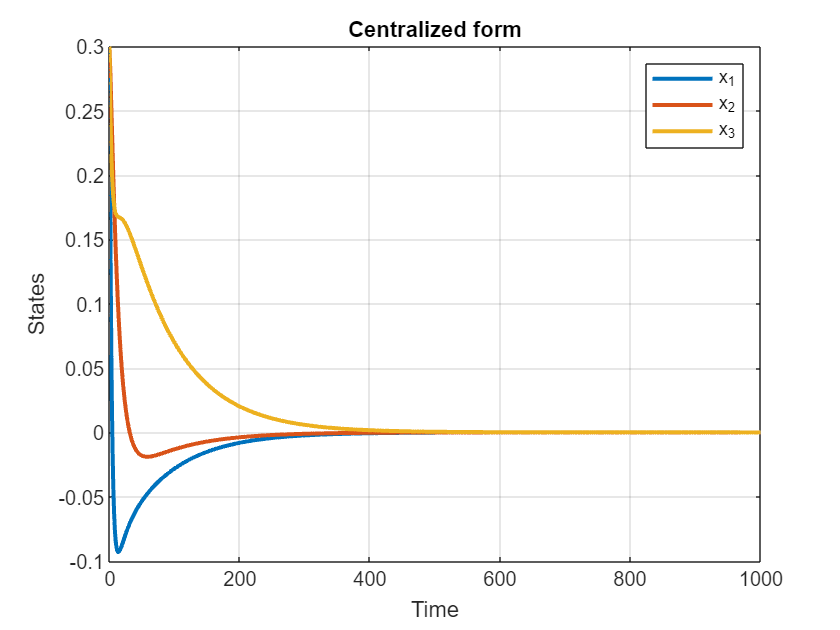

plot(t_cen,x_cen,'linewidth',2)
grid on
xlabel('Time')
ylabel('States')
title('Centralized form')
legend('x_1','x_2','x_3')

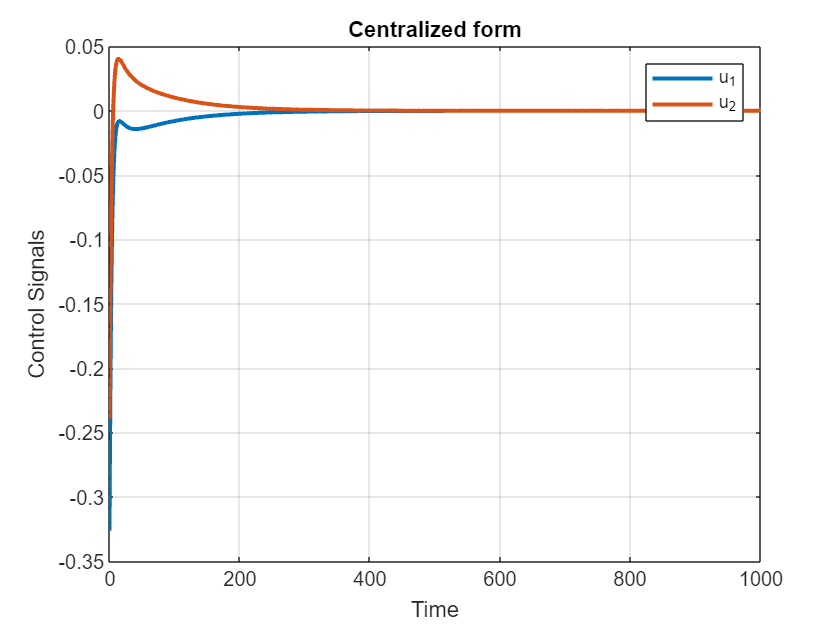


figure
plot(t_cen,u_cen,'linewidth',2)
grid on
xlabel('Time')
ylabel('Control Signals')
title('Centralized form')
legend('u_1','u_2')

pts_cen = 0;   %previous time step
x_Transpose_cen = x_cen';
J_cen=0;

 for i = 1:length(t_cen)-1
     dt=t_cen(i)-pts_cen; 
     pts_cen=t_cen(i);
     S_cen = (x_Transpose_cen(i,:)*Q*x_cen(:,i))*dt;
     J_cen = S_cen+J_cen;
 end
 J_cen

J_cen = 2.9810

# Design in a Decentralized Structure

 sys=ss(G,'minimal');
A_new = sys.A

A_new =          0   -0.0457         0
    0.0312   -0.0786         0
         0         0   -0.0100


B_new = sys.B

B_new =     0.2011    0.1829
         0         0
    0.0720    0.0600


C_new = sys.C

C_new =          0    0.5000         0
         0         0    0.2500


D_new = sys.D

D_new =      0     0
     0     0


#### Define the Q and R matrices for the LQR controller and calculate the corresponding K matrix.

A11=[0	-0.0457;
    0.0312	-0.0786];
B11=[0.2011	0.1829;
     0        0];
K11=lqr(A11,B11,[1 0;0 1],[1 0;0 1])

K11 =     0.7417    0.0162
    0.6745    0.0148



A22=-0.0100;
B22=[0.0720	0.0720];
K22 = lqr(A22,B22,[1],[1 0;0 1])

K22 =     0.6411
    0.6411


K_dec=[0.7417	0.0162 0.6411;
       0.6745	0.0148 0.6411]

K_dec =     0.7417    0.0162    0.6411
    0.6745    0.0148    0.6411


tspan = [0 1000]; % Time span for the simulation
x0 = [0.3; 0.3; 0.3]; % Initial state vector

% Run the ODE solver
[t_dec, x_dec] = ode45(@MySystem2_dec, tspan, x0);

% Transpose x if needed for further analysis
x_dec = x_dec';

u_dec = -K_dec * x_dec; % Control inputs

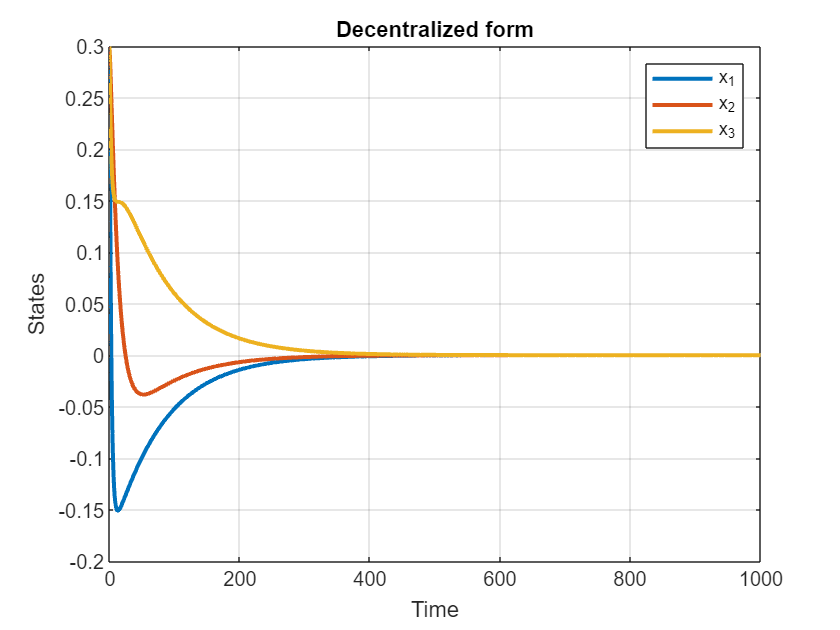

plot(t_dec,x_dec,'linewidth',2)
grid on
xlabel('Time')
ylabel('States')
title('Decentralized form')
legend('x_1','x_2','x_3')

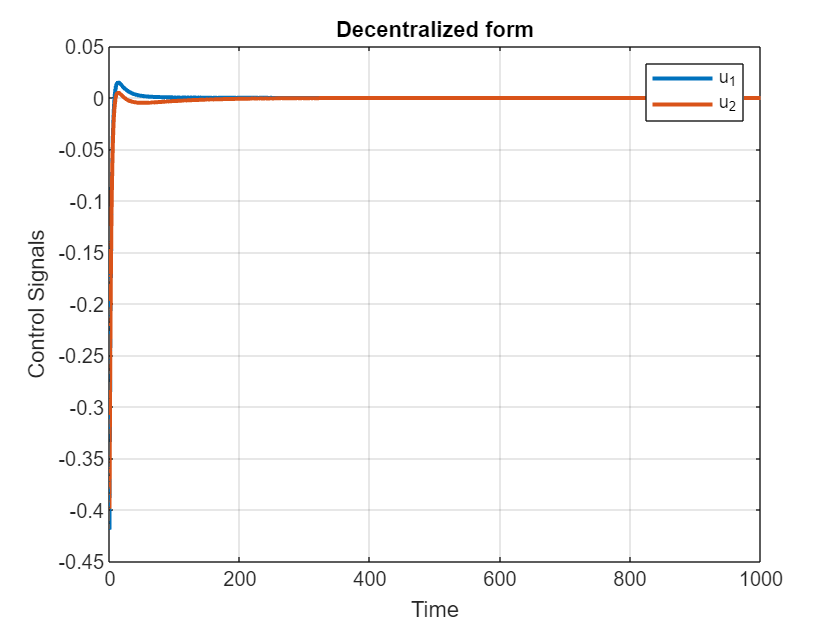

figure
plot(t_dec,u_dec,'linewidth',2)
grid on
xlabel('Time')
ylabel('Control Signals')
title('Decentralized form')
legend('u_1','u_2')

pts_dec = 0;   %previous time step
x_Transpose_dec = x_dec';
J_dec=0;

 for i = 1:length(t_dec)-1
     dt=t_dec(i)-pts_dec; 
     pts_dec=t_dec(i);
     S_dec = (x_Transpose_dec(i,:)*Q*x_dec(:,i))*dt;
     J_dec = S_dec+J_dec;
 end
 J_dec

J_dec = 3.3175